% This code was generated via ChatGPT 5.4 ("extended thinking").


## F-16A Level 1 Sizing Analysis — Class-Based Example

% This live script performs a Level 1 sizing pass for the F-16A example using
% the toolkit classes supplied with the project.
%
% Main objects used:
%   * AircraftDesign
%   * GeometryLevel1
%   * AeroLevel1
%   * PropulsionLevel1
%   * WeightLevel1
%   * MissionAnalysisLevel1
%   * ConstraintAnalysisClass
%   * Requirements
%   * SizingClassLevel1
%
% The script assumes the corresponding class files, import utilities, design
% workbook, requirements table, constraints table, and mission profile are on
% the MATLAB path.

clear;

%% Project setup
% Set this to the folder containing your classes, import utilities, design
% spreadsheet/workbook, requirements file, constraints file, and mission data.
projectRoot = pwd;
addpath(projectRoot);

% Change these names only if your local files use different names.
designName       = "F-16A Block 50";
requirementsName = "Requirements";
constraintsName  = "Constraints";
missionName      = "CAP";


## Create the aircraft design object

% AircraftDesign is the project-level object. It imports the design geometry,
% fuselage data, propulsion data, weight data, general aircraft data, and
% requirements reference.

design = AircraftDesign( ...
     designName, ...
     RequirementsName = requirementsName, ...
     ConstraintsName  = constraintsName, ...
     AutoLoad         = true);


% Keep the constraints filename explicit in case the design constructor was
% given a blank or nonstandard value.
if strlength(string(design.constraints_filename)) == 0
     design.constraints_filename = constraintsName;
end

disp("AircraftDesign object created:")

AircraftDesign object created:


disp(design)

  AircraftDesign with properties:

                     Name: "F-16A Block 50"
                     geom: [1×1 struct]
                  general: [1×1 struct]
               propulsion: [1×1 struct]
          propulsion_type: "low bpr turbofan"
                n_engines: []
                 CivOrMil: []
                     role: []
                  weights: [1×1 struct]
                     type: "Jet fighter"
              wing_config: []
              tail_config: []
            fuselage_type: []
               nose_shape: []
             requirements: [1×1 struct]
    requirements_filename: []
     constraints_filename: "Constraints"
            WeightResults: []
              AeroResults: []
        PropulsionResults: []
           internalvolume: []


## Build the Level 1 analysis objects

% These objects are intentionally lower-fidelity than the Level 3 versions.
% They rely on historical estimates, tabulated assumptions, and simple mission
% weight fractions/Breguet-style estimates.


% Compute required constraints
% constraint_obj.constraint_analysis;

## Weight

weight_obj       = F16WeightLevel1(design);

## Geometry

geometry_obj     = F16GeometryLevel1(design, weight_obj);

geometry_obj.design.S_wet = geometry_obj.get_design_S_wet("jet fighter", weight_obj.W_TO_guess);

## Aerodynamics object

Initialize some things for the Aero object

aero_obj         = F16AeroLevel1("jet fighter", geometry_obj, weight_obj);
aero_obj.Cf = AeroLevel1.get_Cf("air force fighter", 1);

% Get e_osw_clean
aero_obj.e_osw_clean = aero_obj.get_e_osw(geometry_obj.mainwings.AR, geometry_obj.mainwings.LE_sweep);

% Get e_osw_TO, Delta_CD0_TO
[aero_obj.Delta_CD0_TO, aero_obj.e_osw_TO] = aero_obj.get_Delta_CD0("takeoff", "mean");

% Get e_osw_Landing, Delta_CD0_Landing
[aero_obj.Delta_CD0_Landing, aero_obj.e_osw_Landing] = aero_obj.get_Delta_CD0("landing", "mean");

% Get Delta_CD0_geardown
[aero_obj.Delta_CD0_geardown, sorry_nothing] = aero_obj.get_Delta_CD0("geardown", "mean");

% Get Cf
aero_obj.Cf = aero_obj.tab_Cf("air force fighter", 1);

% Compute CD0
CD0 = aero_obj.get_CD0(aero_obj.Cf, geometry_obj.design.S_wet, geometry_obj.mainwings.S_ref);

% Get CL_minD
% aero_obj.CL_minD = 0.02843; % Hardcoded from Brandt
% Need CL_min
n = 100;
M_array = linspace(0, 1.6, n)';
h_alt_array = linspace(0, 40000, n)';
statevector = [M_array, h_alt_array];
q_array = AeroUtils.compute_q(statevector);
CL = AeroUtils.compute_CL(weight_obj.W_TO_guess, q_array, geometry_obj.mainwings.S_ref);
aero_obj.K = 1/(pi*aero_obj.e_osw_clean*geometry_obj.mainwings.AR);
CD = aero_obj.get_CD(CD0, aero_obj.K, CL);
aero_obj.CL_minD = min(CL./CD);
aero_obj.CL_minD = aero_obj.get_CL_minD("cambered", aero_obj.CL_minD, CD0);

% Get CL_max_TO
aero_obj.CL_max_TO = aero_obj.get_CL_max_values("fighter", "takeoff", "mean");

% Get CL_max_land
aero_obj.CL_max_Land = aero_obj.get_CL_max_values("fighter", "landing", "mean");

% Get CL_max_clean
aero_obj.CL_max_clean = aero_obj.get_CL_max_values("fighter", "clean", "mean");

## Propulsion

propulsion_obj   = F16PropulsionLevel1(design);

## Mission

mission_obj      = F16MissionAnalysisLevel1(missionName);

## Constraints

Build the constraints.

constraint_obj   = F16ConstraintAnalysis();
% Need to update the aerodynamic constraints for each given constraint
% (altitude, mach number)

% Get table of state vectors (mach number, altitude) for each constraint
% (constraint name)
constraints_table = Import_Constraints(constraintsName);

constraints_length = length(constraints_table.Altitude_ft_)

constraints_length = 8


% Load up miscellaneous constraints
beta = constraints_table.W_Wto;
n = constraints_table.n;
mu = constraints_table.SurfaceFrictionCoefficient_mu_;
Ps = constraints_table.PS_ft_s_;
distance = constraints_table.Distance_ft_;

% Clean up inputs before things get messy
Ps(isnan(Ps)==1)=0;
n(isnan(n)==1)=0;
distance(isnan(distance)==1)=0;
mu(isnan(mu)==1)=0;


% Get the Mach number and altitude
M = constraints_table.MachNumber;
h_alt = constraints_table.Altitude_ft_;
state_vector = [M, h_alt];

% Set up geometry stuff
AR = geometry_obj.mainwings.AR;
LE_sweep_deg = geometry_obj.mainwings.LE_sweep;
Cf = aero_obj.Cf; % Compute this
S_wet = geometry_obj.get_design_S_wet("jet fighter", weight_obj.W_TO_guess);
S_ref = geometry_obj.mainwings.S_ref;
% e_osw = aero_obj.e_osw;
T_SL_dry = propulsion_obj.T_SL_dry;
T_SL_wet = propulsion_obj.T_SL_wet;
gamma = 1.4;

W_S = constraint_obj.Wto_S_range;

% Get density at sea level
[T, a, P, rho_SL] = atmosisa(0);

% Convert rho_SL to slugs
rho_SL = rho_SL*0.00194032033; % Convert from kg/m^3 -> imperial units

for i=1:constraints_length
     current_constraint = constraints_table.Row{i}
     AB_percent = constraints_table.AB_(i);

     M = state_vector(i,1);
     h_alt = state_vector(i,2);
     newstatevector = [M, h_alt];

     % Get density at current altitude
     [T, a, P, rho] = atmosisa(h_alt*0.3048);

     % Convert rho to slugs
     rho = rho*0.00194032033; % Convert from kg/m^3 -> imperial units

     % Convert a to ft/s
     a = a*3.2808399;

     if isnan(AB_percent)==true
          AB_percent = 1.0;
     elseif (AB_percent > 1.0)
          AB_percent = AB_percent/100;
     elseif (0.0 < AB_percent < 1.0)
          % Do nothing
     else
          error("Error handler.") % Just in case something weird happens.
     end

     % This thing breaks for "takeoff" and "landing" segments.
     % Need takeoff/landing velocity for computations (CD0, alpha,
     % alpha_dry/wet). To get that velocity, I need the weight. To get the
     % weight, I need the velocity... I can start with the guess weight.
     if (current_constraint == "Takeoff")
          % Do takeoff calculations
          % V = 168; % Hardcoded takeoff velocity (ft/s)
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_TO, rho)
               V_TO = 1.2*V_stall;
               M_TO = V_TO./a;

               takeoff_statevector = [M_TO, h_alt];

               q_TO = AeroUtils.compute_q(takeoff_statevector);

               [K1_TO, K2_TO] = aero_obj.get_K(AR, aero_obj.e_osw_TO, M_TO, LE_sweep_deg, aero_obj.CL_minD);
               % [aero_obj.e_osw_TO, CD0, V, q] = constraint_obj.get_aero_constraints(takeoff_statevector, aero_obj.e_osw_TO, Cf, S_wet, S_ref)

               CD0 = aero_obj.get_CD0(aero_obj.Cf, S_wet, S_ref);
               CD0_TO = CD0 + aero_obj.Delta_CD0_TO;
               [alpha_TO, alpha_dry_TO, alpha_wet_TO] = constraint_obj.get_thrust_constraints(takeoff_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               aero_constraints_TO(k, :) = [aero_obj.e_osw_TO, K1_TO, K2_TO, CD0_TO, V_TO, q_TO];
               thrust_constraints_TO(k, :) = [alpha_TO, alpha_dry_TO, alpha_wet_TO];
          end
          e_osw_TO = aero_constraints_TO(:,1);
          K1_TO = aero_constraints_TO(:,2);
          K2_TO = aero_constraints_TO(:,3);
          V_TO = aero_constraints_TO(:,5);
          % q_takeoff = aero_constraints_takeoff(:,6);

          alpha_TO = thrust_constraints_TO(:,1);
          alpha_dry_TO = thrust_constraints_TO(:,2);
          alpha_wet_TO = thrust_constraints_TO(:,3);
     elseif (current_constraint == "Landing")
          % Do landing calculations
          for k=1:length(W_S)
               V_stall = AeroUtils.V_stall(W_S(k), aero_obj.CL_max_Land, rho)
               V_L = 1.3*V_stall;
               M_L = V_L./a;

               landing_statevector = [M_L, h_alt];

               q_L = AeroUtils.compute_q(takeoff_statevector);

               [K1_L, K2_L] = aero_obj.get_K(AR, aero_obj.e_osw_Landing, M_L, LE_sweep_deg, aero_obj.CL_minD);
               % [e_osw, CD0, V, q] = constraint_obj.get_aero_constraints(landing_statevector, aero_obj.e_osw_Landing, aero_obj.Cf, S_wet, S_ref)

               CD0 = aero_obj.get_CD0(aero_obj.Cf, S_wet, S_ref);
               CD0_L = CD0 + aero_obj.Delta_CD0_geardown + aero_obj.Delta_CD0_Landing;
               [alpha_L, alpha_dry_L, alpha_wet_L] = constraint_obj.get_thrust_constraints(landing_statevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

               % thrust_constraints(i, :) = [0, 0, 0];
               % aero_constraints(i, :) = [0, 0, 0, 0, 0, 0];
               aero_constraints_L(k, :) = [aero_obj.e_osw_Landing, K1_L, K2_L, CD0_L, V_L, q_L];
               thrust_constraints_L(k, :) = [alpha_L, alpha_dry_L, alpha_wet_L];
          end
          e_osw_L = aero_constraints_L(:,1);
          K1_L = aero_constraints_L(:,2);
          K2_L = aero_constraints_L(:,3);
          V_L = aero_constraints_L(:,5);
          q_L = aero_constraints_L(:,6);

          alpha_L = thrust_constraints_L(:,1);
          alpha_dry_L = thrust_constraints_L(:,2);
          alpha_wet_L = thrust_constraints_L(:,3);
     else
          % Compute thrust constraints (alpha_dry, alpha_wet, alpha)
          [alpha, alpha_dry, alpha_wet] = constraint_obj.get_thrust_constraints(newstatevector, T_SL_dry, T_SL_wet, gamma, AB_percent, propulsion_obj)

          % Compute thrust at altitude (sanity check)
          T_alt_wet = PropulsionUtils.thrust_from_lapse(alpha_wet, T_SL_wet)
          T_alt_dry = PropulsionUtils.thrust_from_lapse(alpha_dry, T_SL_dry)

          thrust_constraints(i, :) = [alpha, alpha_dry, alpha_wet];

          % Casey, you REALLY need to clean this up!!!
          aero_obj.e_osw_clean = aero_obj.get_e_osw(AR, geometry_obj.mainwings.LE_sweep);
          [K1, K2] = aero_obj.get_K(AR, aero_obj.e_osw_clean, M, LE_sweep_deg, aero_obj.CL_minD)
          V = AeroUtils.compute_airspeed(newstatevector);
          q = AeroUtils.compute_q(newstatevector);
          % [aero_obj.e_osw_clean, CD0, V, q] = constraint_obj.get_aero_constraints([M, h_alt], aero_obj.e_osw_clean, aero_obj.Cf, S_wet, S_ref)
          CD0 = aero_obj.get_CD0(aero_obj.Cf, S_wet, S_ref);
          aero_constraints(i, :) = [aero_obj.e_osw_clean, K1, K2, CD0, V, q];
     end
end

current_constraint = 'Max Mach'

alpha = 0.5494

alpha_dry = 0.3089

alpha_wet = 0.5494

T_alt_wet = 1.3060e+04

T_alt_dry = 4.6332e+03

K1 = 0.2760

K2 = 0

current_constraint = 'Cruise'

alpha = 0.1391

alpha_dry = 0.2204

alpha_wet = 0.3674

T_alt_wet = 8.7330e+03

T_alt_dry = 3.3066e+03

K1 = 0.1168

K2 = -0.1886

current_constraint = 'Max Alt'

alpha = 0.1875

alpha_dry = 0.1125

alpha_wet = 0.1875

T_alt_wet = 4.4559e+03

T_alt_dry = 1.6871e+03

K1 = 0.1168

K2 = -0.1886

current_constraint = 'Combat Subsonic'

alpha = 0.7526

alpha_dry = 0.4516

alpha_wet = 0.7526

T_alt_wet = 1.7890e+04

T_alt_dry = 6.7738e+03

K1 = 0.1168

K2 = -0.1886

current_constraint = 'Combat Supersonic'

alpha = 0.6007

alpha_dry = 0.3546

alpha_wet = 0.6007

T_alt_wet = 1.4278e+04

T_alt_dry = 5.3187e+03

K1 = 0.2261

K2 = 0

current_constraint = 'Excess Power'

alpha = 0.8608

alpha_dry = 0.5028

alpha_wet = 0.8608

T_alt_wet = 2.0462e+04

T_alt_dry = 7.5426e+03

K1 = 0.1168

K2 = -0.1886

current_constraint = 'Takeoff'

V_stall = 99.4949

alpha_TO = 1.0000

alpha_dry_TO = 0.5996

alpha_wet_TO = 1.0000

V_stall = 115.6026

alpha_TO = 1.0000

alpha_dry_TO = 0.5994

alpha_wet_TO = 1.0000

V_stall = 129.7255

alpha_TO = 0.9999

alpha_dry_TO = 0.5993

alpha_wet_TO = 0.9999

V_stall = 142.4550

alpha_TO = 0.9999

alpha_dry_TO = 0.5991

alpha_wet_TO = 0.9999

V_stall = 154.1368

alpha_TO = 0.9999

alpha_dry_TO = 0.5989

alpha_wet_TO = 0.9999

V_stall = 164.9936

alpha_TO = 0.9998

alpha_dry_TO = 0.5987

alpha_wet_TO = 0.9998

V_stall = 175.1788

alpha_TO = 0.9998

alpha_dry_TO = 0.5986

alpha_wet_TO = 0.9998

V_stall = 184.8036

alpha_TO = 0.9997

alpha_dry_TO = 0.5984

alpha_wet_TO = 0.9997

V_stall = 193.9512

alpha_TO = 0.9997

alpha_dry_TO = 0.5982

alpha_wet_TO = 0.9997

V_stall = 202.6865

alpha_TO = 0.9996

alpha_dry_TO = 0.5980

alpha_wet_TO = 0.9996

V_stall = 211.0605

alpha_TO = 0.9995

alpha_dry_TO = 0.5978

alpha_wet_TO = 0.9995

V_stall = 219.1148

alpha_TO = 0.9995

alpha_dry_TO = 0.5976

alpha_wet_TO = 0.9995

V_stall = 226.8833

alpha_TO = 0.9994

alpha_dry_TO = 0.5974

alpha_wet_TO = 0.9994

V_stall = 234.3944

alpha_TO = 0.9993

alpha_dry_TO = 0.5972

alpha_wet_TO = 0.9993

V_stall = 241.6722

alpha_TO = 0.9992

alpha_dry_TO = 0.5970

alpha_wet_TO = 0.9992

V_stall = 248.7372

alpha_TO = 0.9991

alpha_dry_TO = 0.5968

alpha_wet_TO = 0.9991

V_stall = 255.6070

alpha_TO = 0.9990

alpha_dry_TO = 0.5966

alpha_wet_TO = 0.9990

V_stall = 262.2969

alpha_TO = 0.9989

alpha_dry_TO = 0.5963

alpha_wet_TO = 0.9989

V_stall = 268.8204

alpha_TO = 0.9988

alpha_dry_TO = 0.5961

alpha_wet_TO = 0.9988

V_stall = 275.1893

alpha_TO = 0.9986

alpha_dry_TO = 0.5959

alpha_wet_TO = 0.9986

V_stall = 281.4140

alpha_TO = 0.9985

alpha_dry_TO = 0.5957

alpha_wet_TO = 0.9985

current_constraint = 'Landing'

V_stall = 89.5191

alpha_L = 1.0000

alpha_dry_L = 0.5996

alpha_wet_L = 1.0000

V_stall = 104.0118

alpha_L = 1.0000

alpha_dry_L = 0.5994

alpha_wet_L = 1.0000

V_stall = 116.7186

alpha_L = 0.9999

alpha_dry_L = 0.5993

alpha_wet_L = 0.9999

V_stall = 128.1718

alpha_L = 0.9999

alpha_dry_L = 0.5991

alpha_wet_L = 0.9999

V_stall = 138.6824

alpha_L = 0.9999

alpha_dry_L = 0.5990

alpha_wet_L = 0.9999

V_stall = 148.4506

alpha_L = 0.9998

alpha_dry_L = 0.5988

alpha_wet_L = 0.9998

V_stall = 157.6146

alpha_L = 0.9998

alpha_dry_L = 0.5986

alpha_wet_L = 0.9998

V_stall = 166.2743

alpha_L = 0.9998

alpha_dry_L = 0.5985

alpha_wet_L = 0.9998

V_stall = 174.5048

alpha_L = 0.9997

alpha_dry_L = 0.5983

alpha_wet_L = 0.9997

V_stall = 182.3642

alpha_L = 0.9996

alpha_dry_L = 0.5981

alpha_wet_L = 0.9996

V_stall = 189.8986

alpha_L = 0.9996

alpha_dry_L = 0.5979

alpha_wet_L = 0.9996

V_stall = 197.1453

alpha_L = 0.9995

alpha_dry_L = 0.5978

alpha_wet_L = 0.9995

V_stall = 204.1349

alpha_L = 0.9994

alpha_dry_L = 0.5976

alpha_wet_L = 0.9994

V_stall = 210.8930

alpha_L = 0.9994

alpha_dry_L = 0.5974

alpha_wet_L = 0.9994

V_stall = 217.4411

alpha_L = 0.9993

alpha_dry_L = 0.5972

alpha_wet_L = 0.9993

V_stall = 223.7977

alpha_L = 0.9992

alpha_dry_L = 0.5970

alpha_wet_L = 0.9992

V_stall = 229.9787

alpha_L = 0.9991

alpha_dry_L = 0.5968

alpha_wet_L = 0.9991

V_stall = 235.9978

alpha_L = 0.9990

alpha_dry_L = 0.5966

alpha_wet_L = 0.9990

V_stall = 241.8672

alpha_L = 0.9989

alpha_dry_L = 0.5964

alpha_wet_L = 0.9989

V_stall = 247.5975

alpha_L = 0.9988

alpha_dry_L = 0.5961

alpha_wet_L = 0.9988

V_stall = 253.1982

alpha_L = 0.9987

alpha_dry_L = 0.5959

alpha_wet_L = 0.9987


% Build tables for aero constraints
aero_constraints_table = array2table(aero_constraints, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

aero_constraints_table = 6×6 table
                          e_osw       K1          K2         CD0         V         q   
                         _______    _______    ________    ________    ______    ______
    Max Mach             0.90862    0.27603           0    0.026962    1549.6    850.68
    Cruise               0.90862    0.11677    -0.18857    0.026962    842.57    251.52
    Max Alt              0.90862    0.11677    -0.18857    0.026962    842.23    128.33
    Combat Subsonic      0.90862    0.11677    -0.18857    0.026962    902.06    515.26
    Combat Supersonic    0.90862     0.2261           0    0.026962    1355.9     651.3
    Excess Power         0.90862    0.11677

e_osw = aero_constraints(:,1);
K1 = aero_constraints(:,2);
K2 = aero_constraints(:,3);
CD0 = aero_constraints(:,4);
V = aero_constraints(:,5);
q = aero_constraints(:,6);

% Build table for thrust constraints
thrust_constraints_table = array2table(thrust_constraints, "VariableNames",{'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

thrust_constraints_table = 6×3 table
                          alpha     alpha_dry    alpha_wet
                         _______    _________    _________
    Max Mach             0.54943     0.30888      0.54943 
    Cruise               0.13911     0.22044       0.3674 
    Max Alt              0.18746     0.11247      0.18746 
    Combat Subsonic      0.75265     0.45159      0.75265 
    Combat Supersonic    0.60067     0.35458      0.60067 
    Excess Power         0.86082     0.50284      0.86082 

alpha = thrust_constraints(:,1);
alpha_dry = thrust_constraints(:,2);
alpha_wet = thrust_constraints(:,3);

% Make all constraint arrays the same size as the imported arrays (beta, n,
% Ps, etc).


% Compute T/W and wing loading stuff for all constraints
TW_table = constraint_obj.createThrustLoadingTable(aero_constraints_table, beta, alpha, n, q, V, CD0, K1, Ps, W_S)

TW_table =     2.0968    1.5590    1.2440    1.0378    0.8926    0.7853    0.7029    0.6380    0.5856    0.5426    0.5069    0.4767    0.4511    0.4291    0.4102    0.3937    0.3793    0.3668    0.3557    0.3460    0.3374
    2.4915    1.8785    1.5256    1.2998    1.1453    1.0349    0.9538    0.8929    0.8467    0.8116    0.7848    0.7646    0.7497    0.7390    0.7319    0.7277    0.7259    0.7262    0.7283    0.7319    0.7369
    1.0015    0.7897    0.6765    0.6113    0.5731    0.5517    0.5413    0.5386    0.5415    0.5485    0.5587    0.5714    0.5861    0.6024    0.6200    0.6388    0.6584    0.6789    0.7000    0.7218    0.7440
    1.0216    0.8169    0.7107    0.6525    0.6214    0.6070    0.6037    0.6080    0.6180    0.6320    0.6493    0.6690    0.6908    0.7141    0.7388    0.7646    0.7913    0.8188    0.8470    0.8758    0.9050
    1.4801    1.1075    0.8910    0.7506    0.6531    0.5820    0.5284    0.4870    0.4543    0.4283    0.4073    0.3903    0.3765    0.3651    0



% Takeoff and landing analysis
% CALCULATIONS

T_Wto_takeoff = ConstraintAnalysisClass.takeoff_constraint(W_S, 1.2, beta(7), alpha_TO', rho, aero_obj.CL_max_TO, distance(7), CD0_TO, mu(7))

T_Wto_takeoff =     0.1027    0.1220    0.1414    0.1608    0.1802    0.1996    0.2190    0.2384    0.2578    0.2772    0.2966    0.3160    0.3354    0.3549    0.3743    0.3937    0.4132    0.4326    0.4521    0.4715    0.4910


Wto_S_Landing = ConstraintAnalysisClass.landing_constraint(distance(8), beta(8), rho, aero_obj.CL_max_Land, CD0_L, mu(8))

Wto_S_Landing = 206.8744




% Package the aero and thrust results into a table format to use the
% pre-existing graph functions.
new_constraints_array = [aero_constraints, thrust_constraints];
new_constraints_table = array2table(new_constraints_array, "VariableNames",{'e_osw', 'K1', 'K2', 'CD0', 'V', 'q', 'alpha', 'alpha_dry', 'alpha_wet'}, "RowNames", {'Max Mach', 'Cruise', 'Max Alt', 'Combat Subsonic', 'Combat Supersonic', 'Excess Power'})

new_constraints_table = 6×9 table
                          e_osw       K1          K2         CD0         V         q        alpha     alpha_dry    alpha_wet
                         _______    _______    ________    ________    ______    ______    _______    _________    _________
    Max Mach             0.90862    0.27603           0    0.026962    1549.6    850.68    0.54943     0.30888      0.54943 
    Cruise               0.90862    0.11677    -0.18857    0.026962    842.57    251.52    0.13911     0.22044       0.3674 
    Max Alt              0.90862    0.11677    -0.18857    0.026962    842.23    128.33    0.18746     0.1124


% Trim takeoff and landing from constraints table
% constraints_table = [constraints_table, new_constraints_table]

% Get optimal wing loading and T/W
[constraint_obj.optimal_WS, constraint_obj.min_TW] = constraint_obj.solveOptimalPoint(TW_table, T_Wto_takeoff, W_S)

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 125
                min_TW: 0.7685
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [2.4915 1.8785 1.5256 1.2998 1.1453 1.0349 0.9559 0.9173 0.8861 0.8603 0.8387 0.8203 0.8045 0.7909 0.7790 0.7685 0.7913 0.8188 0.8470 0.8758 0.9050]
     constraints_table: []
    constraints_struct: []

constraint_obj =   F16ConstraintAnalysis with properties:

           Wto_S_range: [20 27 34 41 48 55 62 69 76 83 90 97 104 111 118 125 132 139 146 153 160]
              TW_table: []
         T_Wto_takeoff: []
            optimal_WS: 125
                min_TW: 0.7685
               Landing: []
         Wto_S_landing: []
                 T0_W0: []
              W0_S_ref: []
        T_Wto_required: [2.4915 1.8785 1.5256 1.2998 1.1453 1.0349 0.9559 0.9173 0.8861 0.8603 0.8387 0.8203 0.8045 0.7909 0.7790 0.7685 0.7913 0.8188 0.8470 0.8758 0.9050]
     constraints_table: []
    constraints_struct: []

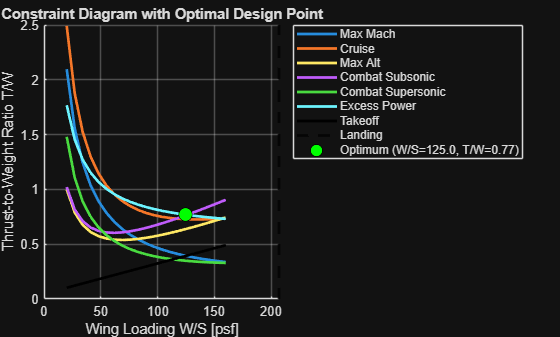


constraint_obj.plotConstraintDiagram(W_S, TW_table, T_Wto_takeoff, Wto_S_Landing, constraint_obj.optimal_WS, constraint_obj.min_TW, {constraints_table.Row{:}})

## Requirements

requirements_obj = Requirements(design);

## Run the project sizing class

% OLD COMMENT IGNORE THIS
% This calls the F16SizingLevel1 method directly. The method returns the
% converged W_TO. In the current class definition, results_table is assigned
% inside the method, but the class itself does not inherit handle, so the table
% may not persist outside the method depending on your inheritance tree.
% OLD COMMENT IGNORE THIS

% INITIALIZE THE SIZING OBJECT
sizing_obj       = F16SizingLevel1();


tol = 1e-3;
max_iteration = 40;
results = [];

LD_max = aero_obj.LD_max;
W_fixed = weight_obj.W_fixed;

W_S = constraint_obj.optimal_WS;
T_W = constraint_obj.min_TW;

W_TO = weight_obj.W_TO_guess;
S_ref = geometry_obj.mainwings.S_ref;

mission_data = mission_obj.missiondata;

for iteration = 1:max_iteration

     [weight_obj.total_fuel_used, weight_obj.fuel_fraction] = mission_obj.get_mission_fuel(propulsion_obj, mission_data, W_TO, LD_max);
     weight_obj.OEW = weight_obj.get_OEW(design.type, W_TO);
     weight_obj.OEW_frac = weight_obj.OEW/W_TO;

     W_TO_new = sizing_obj.compute_TOGW(weight_obj.OEW, weight_obj.total_fuel_used, W_fixed);
     difference = W_TO_new - W_TO;
     percent_diff = 100 * difference/W_TO;

     results(end+1, :) = [W_TO, W_fixed, weight_obj.fuel_fraction, weight_obj.OEW_frac, weight_obj.OEW, W_TO_new, difference, percent_diff, S_ref];

     if abs(difference) < tol
          break;
     end
     W_TO = W_TO_new;
     % T0 = T_W*W_TO;
     % S_ref = W_TO/W_S;

end
weight_obj.W_TO = W_TO;
sizing_obj.results_table = array2table(results, 'VariableNames', {'WTO', 'W_fixed', 'Fuel_fraction', 'Empty_weight_fraction', 'Empty_weight', 'WTO_new', 'Difference', 'Percent_Diff', 'S_ref'});
W_TO_final = W_TO_new;
sizing_output = sizing_obj.results_table;
disp(sizing_output);

     WTO     W_fixed    Fuel_fraction    Empty_weight_fraction    Empty_weight    WTO_new    Difference    Percent_Diff    S_ref
    _____    _______    _____________    _____________________    ____________    _______    __________    ____________    _____
    45000     5100         0.25039              0.58116              26152         41882       -3117.9         -6.9286      300 
    41882     5100         0.24985              0.58661              24569         39541       -2341.4         -5.5904      300 
    39541     5100          0.2494              0.59102              23369         37772       -1768.4         -4.4722      300 
    37772     5100         0.24901              0

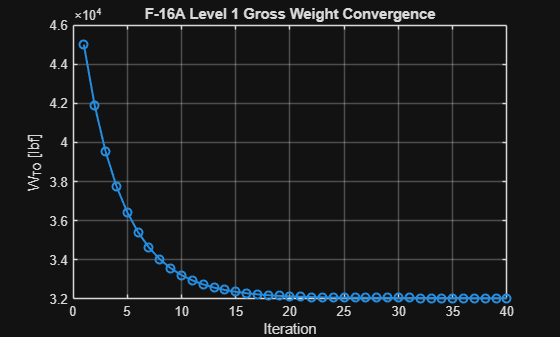


% propulsion_obj.T0 = T0;

figure('Name', 'Level 1 Gross Weight Convergence');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.WTO, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('W_{TO} [lbf]');
title('F-16A Level 1 Gross Weight Convergence');

## Plot closure error

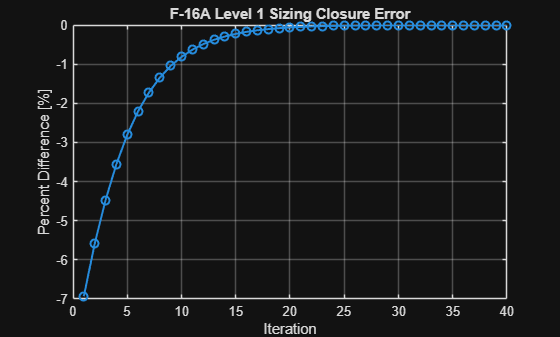

figure('Name', 'Level 1 Closure Error');
plot(1:height(sizing_obj.results_table.WTO), sizing_obj.results_table.Percent_Diff, '-o', 'LineWidth', 1.5);
grid on;
xlabel('Iteration');
ylabel('Percent Difference [%]');
title('F-16A Level 1 Sizing Closure Error');

## Plot final weight breakdown

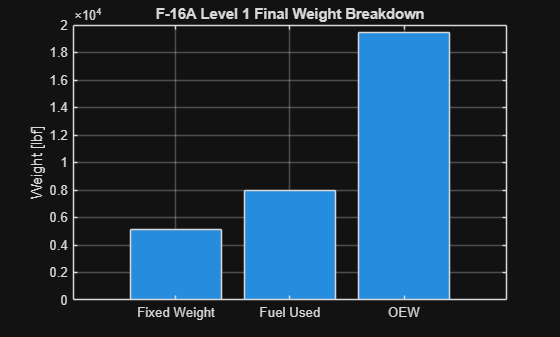

weightBreakdown = table( ...
     categorical(["OEW"; "Fuel Used"; "Fixed Weight"]), ...
     [sizing_output.Empty_weight(length(sizing_output.WTO)); ...
     sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO)); ...
     sizing_output.W_fixed(length(sizing_output.WTO))], ...
     'VariableNames', {'Component', 'Weight_lbf'});

figure('Name', 'Level 1 Final Weight Breakdown');
bar(weightBreakdown.Component, weightBreakdown.Weight_lbf);
grid on;
ylabel('Weight [lbf]');
title('F-16A Level 1 Final Weight Breakdown');

## Save results into the AircraftDesign object

% % AircraftDesign is a handle class, so these assignments persist on the design
% % object during this MATLAB session.
%
design.WeightResults.Level1SizingTable = sizing_output;
design.WeightResults.W_TO              = sizing_output.WTO(length(sizing_output.WTO));
design.WeightResults.OEW               = sizing_output.Empty_weight(length(sizing_output.WTO));
design.WeightResults.FuelUsed          = sizing_output.Fuel_fraction(length(sizing_output.WTO)).*sizing_output.WTO(length(sizing_output.WTO));

design.AeroResults.Level1.LDmax         = aero_obj.LD_max;
design.AeroResults.Level1.AR_wetted     = aero_obj.AR_wet;
design.AeroResults.Level1.S_wet         = geometry_obj.design.S_wet;

% design.PropulsionResults.Level1.T0      = propulsion_obj.T0;
design.PropulsionResults.Level1.TSFC    = propulsion_obj.TSFC;